% actual transfer function
figure(1);
sys = tf([24.46], [1, 0, -326.66]);
pole(sys)

ans =    18.0737
  -18.0737


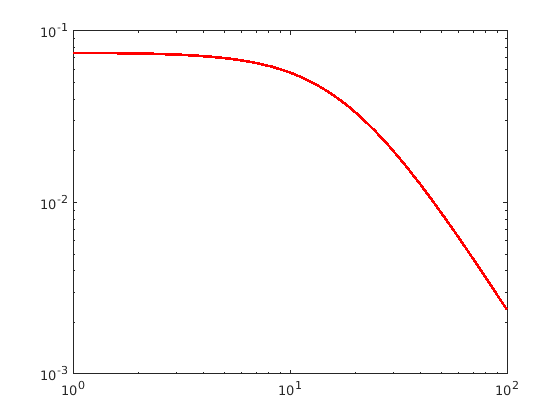

[bode_mag, bode_phase, bode_freq] = bode(sys);
bode_mag = reshape(bode_mag, [], 1);
bode_phase = reshape(bode_phase, [], 1);
loglog(bode_freq, bode_mag, 'r', 'LineWidth', 2)

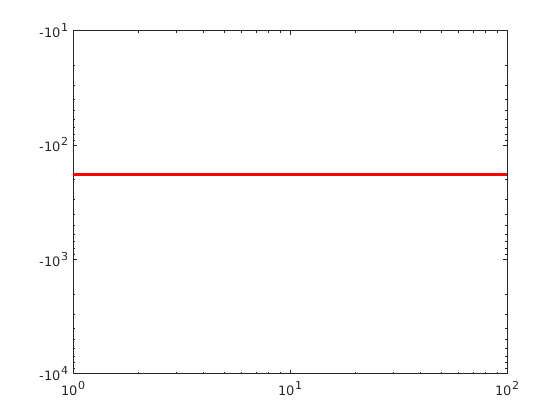

figure(2);
loglog(bode_freq, bode_phase, 'r', 'LineWidth', 2)

m = 0.003                 

m = 0.0030

g = 9.8                            

g = 9.8000

R = 2.41

R = 2.4100

C = .5*(8.70819*(10^-6))  

C = 4.3541e-06


x_0 = -0.03               

x_0 = -0.0300

ground = -0.2             

ground = -0.2000

    
K_nov =  C * (1/(x_0^2))

K_nov = 0.0048

Kv = C * (1/(x_0^2))

Kv = 0.0048

Kx_nov = C * (2/(x_0^3))        

Kx_nov = -0.3225

v_0 = (m*g) / (x_0*Kx_nov - Kv + K_nov)   

v_0 = 3.0385


K = C * (v_0/(x_0^2))

K = 0.0147

Kx = C * (2*v_0/(x_0^3))

Kx = -0.9800



% PID
% Kp = 1;
% Ki = 19;
% Kd = .01;
% Ck = -1;
% Vin = 3;
% v_bar = Vin-v_0;
% 
% Cont = tf([Ck*Kd, Ck*Kp, Ck*Ki], [1, 0]);
% 
% Gcl = tf([Ck*v_bar*Kv*Kd, Ck*v_bar*Kv*Kp, Ck*v_bar*Kv*Ki], [m, (v_bar*Kv*Kd), (Kx+v_bar*Kv*Kp), v_bar*Kv*Ki])
% 
% [loc, val] = rlocus(Gcl, 1000000)
% 
% z1 = (-Kp + sqrt(Kp^2 - 4*Kd*Ki))/(2*Kd)
% z2 = (-Kp - sqrt(Kp^2 - 4*Kd*Ki))/(2*Kd)

Kp = .15;
Kd = .01;

GC = tf([Kv*Kd, Kv*Kp], [m, 0, Kx])


GC =
 
  4.838e-05 s + 0.0007257
  -----------------------
     0.003 s^2 - 0.98
 
Continuous-time transfer function.



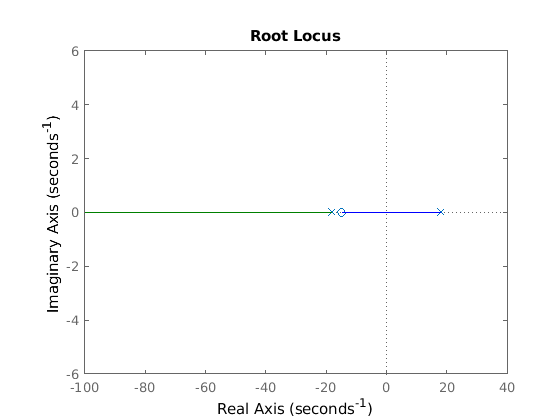

rlocus(GC)

[loc1, val1] = rlocus(GC, 1400)

loc1 =   -22.0328
   -0.5440


val1 = 1400


Ck = val1;
Gcl = tf([Ck*Kv*Kd, Ck*Kv*Kp], [m, Kv*Kd, (Kx + Kv*Kp)])


Gcl =
 
         0.06773 s + 1.016
  --------------------------------
  0.003 s^2 + 4.838e-05 s - 0.9793
 
Continuous-time transfer function.



pole(Gcl)

ans =   -18.0753
   18.0592
